# Actividad 2: Optimización sin restricciones

**Grupo 2:** Jorge David Ávila Álvarez, Miguel Moreno Sánchez, Ainhoa Muñiz Quintana, Lorea Páramo Arana, Pablo Ruiz Molina

**Fecha: **10.01.2025

% Limpieza de la consola, variables y figuras
clc; clear; close all

## Introducción

En este laboratorio estudiaremos el siguiente problema de optimización sin reestricciones. Encontrar la curva $u(x)$ que conecta los puntos $\left(0,1\right)$ y $\left(1,1\right)$ tal que el área de la superficie de revolución alrededor del eje $x$ sea mínima.

El área de la superficie de revolución para una curva $u(x)
$ se define como la integral $2\pi\int_0^1 u(x) \sqrt{1+[u'(x)]^2} dx $. Sin embargo, minimizar esta expresión es equivalente a minimizar $I(u)= \int_0^1 u(x) \sqrt{1+[u'(x)]^2} dx $, en dónde hemos normalizado la expresión anterior eliminando el factor $2\pi$ para facilitar los cálculos.

Para resolver este problema, vamos a realizar una aproximación del problema continuo mediante una discretización del intervalo $[0,1]$ en $n$ intervalos de la forma $\left[\frac{j}{n}, \frac{j+1}{n}\right]$, para $0\leq j\leq n-1$. De está forma el problema se reduce a encontrar los puntos $u_j = u\left(\frac{j}{n}\right)$ que minimicen a la expresión:


$$T(u)=\sum_{j=0}^{n-1}T_j(u)  \text{   con   } T_j(u)=\frac{(u_j + u_{j+1})\sqrt{1+n^2[u_{j+1}-u_j]^2}}{2n}$$


Donde $T(u)$ es la aproximación por el método de los trapecios de la integral $I(u)$.

Cabe destacar que, debido a que la curva $u(x)$ debe unir los puntos $(0,1)$ y $(1,1)$, se debe imponer que $u_0=u_n=1$. De está forma hemos aproximado el problema original por un problema de optimización sin reestricciones de dimensión $n-1$. Para resolver este problema se hace uso del Método del Gradiante Descedente utilizando un paso variable.

Respecto a la metodología, en primer lugar se inicializa el número de subintervalos de la partición, la tolerancia máxima permitida y el número máximo de iteraciones. Seguidamente se implementa el algoritmo del Método del Gradiante Descendente de paso variable. Este algoritmo requiere de un método de búesqueda unidimensional, en este trabajo, con el objetivo de comparar, vamos a utilizar tres métodos de búesqueda unidimensional distintos, el método de Búesqueda Dicotómica, Fibonacci y Sección Áurea. En tercer lugar se hace una comparativa en formato tabla y en formato gráfico de los resultados obtenidos usando los tres métodos. Por último se presenta una comparativa con la solución teórica del problema y se presenta una gráfica de la superficie de revolución que minimiza el área.

El trabajo incluye como anexo al final del documento todas las funciones necesarias para la resolución del laboratorio.

## Definir el intervalo [0,1] y discretizarlo en n intervalos 

Por claridad en las visualizaciones gráficas posteriores se utilizará $n =35$ , es decir, partiremos el intervalo en 35 subintervalos. Además, como el método del gradiante requiere de un vector inicial, vamos a definir como véctor de arranque $u^1$ un vector de unos, pues cumple con la condición $u_0^1=u_n^1=1$.

n = 35; % Número de intervalos
x = linspace(0, 1, n+1); % n+1 puntos discretos: incluyendo 0 y 1
% Inicialización de u(x)
u = ones(size(x)); % Inicialización (u(0)=1, u(1)=1) 

## Inicializar el algoritmo

En este apartado se inicializa la tolerancia máxima permitida, el número máximo de iteraciones y el número máximo de iteraciones que le permitimos al método de búesqueda dicotómica para encontrar el tamaño de paso óptimo.

% Parámetros del algoritmo
delta = 1e-6; % Tolerancia para la convergencia
max_iter = 30000; % Número máximo de iteraciones
max_iter_bus = 1000; % Número máximo de iteraciones para el algoritmo de búsqueda dicotómica

% Comparación entre los métodos de búsqueda
metodos = {'Búsqueda Dicotómica', 'Fibonacci', 'Sección Áurea'};
resultados = struct;

## Implementación del Método del Gradiente Descendente

En este apartado se implementa el algoritmo del Método del Gradiante Descendiente. Con el objetivo de afianzar los contenidos de la actividad 1 y comparar resultados, en la implementación del algoritmo se implementan tres métodos de búsqueda unidimensional para hallar el tamaño de paso, los métodos de Búesqueda Dicotómica, Fibonacci y Razón áurea.

Por otro lado, como criterio de parada utilizaremos dos errores. El algoritmo se detendrá cuándo $||\nabla T(u^k)|| < \delta = 10^{-6}$ o cuándo $||u^{k+1}-u^k|| < \delta = 10^{-6}$. Además, para evitar excesivas iteraciones, el algoritmo se detendrá cuándo se llegue al número máximos de iteraciones, establecido en este caso en 30000.

% Bucle para realizar el algoritmo con los tres métodos de búesqueda
% unidimensional.
for metodo = 1:size(metodos, 2) 
iter = 0; 

% Inicializar los errores
error_1 = delta + 1; % Error ||u_{k+1} - u_k||
error_2 = delta + 1; % Error ||grad_f(u_{k+1})||

% Inicialización de u_k y u_{k+1}
u_k = u;
u_k_plus = u_k;

% Inicializar tabla de resultados por iteración
tabla_it = zeros(max_iter, size(u_k_plus, 2) + 3);
tiempo1 = tic;

% Bucle del algritmo del método del gradiante descendente
    while (error_1 > delta || error_2 > delta) && iter < max_iter
        iter = iter +1;
        %% Paso 2: gradiente en el punto actual y tasa de aprendizaje
        gradiente = calculo_gradiente(u_k,n);

        ft = @(t) F(u_k - t * gradiente, n); % función unidimensional 

        % Búsqueda para encontrar el t óptimo con diferentes métodos
        if metodo == 1
            t_k = busqueda_dicotomica(ft, 0, 0.1, delta, max_iter_bus);
        elseif metodo == 2
            [t_k,~,~] = fibo(ft, [0, 0.1], delta);
        else
            [t_k,~,~] = SeccionAurea(ft,delta,0,0.1);
        end
    
        %% Paso 3: actualizar 
        u_k_plus(2:n) = u_k(2:n) - t_k * gradiente(2:n); % Actualizar puntos intermedios
    
        %% Calcular errores
        error_1 = norm(u_k_plus(2:n) - u_k(2:n)); % Diferencia entre puntos sucesivos
        error_2 = norm(gradiente(2:n)); % Tamaño del gradiente
    
        %% Guardar resultados iteración en tabla
        tabla_it(iter, :) = [iter, error_1, error_2, u_k_plus];
    
        % Actualizar u 
        u_k(2:n) = u_k_plus(2:n);
    end
    tiempo_transcurrido = toc(tiempo1); % Detiene el temporizador 1

    % Guardar resultados del método en la tabla
    area = 2 * pi * F(u_k, n); % Cálculo del área con la expresión derivada del arco
    resultados(metodo).tiempo = tiempo_transcurrido;
    resultados(metodo).iteraciones = iter;
    resultados(metodo).area = area;
    resultados(metodo).u_k = u_k;
    resultados(metodo).tabla_it = tabla_it;
end

## Imprimir resultados

En este apartado se muestran los resultados de la aplicación del algoritmo del método del gradiante descendente. Se presentan 3 tablas en las que se recogen los resultados de la optimización utilizando el método de Búsqueda Dicotómica, Fibonacci y Sección Áurea. Además, acompañando a cada tabla, se muestra el tiempo utilizado, el número de iteraciones y la aproximación del área por cada uno de los métodos.

% Generar dinámicamente los nombres de las columnas
variable_names = [{'Iteración'}, {'Error_1', 'Error_2'}, strcat('u', string(0:n))];
% Mostrar las iteraciones deseadas: 5 primeras y 50 últimas

for metodo = 1:3
    fprintf('\nMétodo: %s\n', metodos{metodo});
    fprintf('Tiempo transcurrido: %.6f segundos\n', resultados(metodo).tiempo);
    fprintf('Número de iteraciones: %d\n', resultados(metodo).iteraciones);
    fprintf('Área obtenida: %.6f\n', resultados(metodo).area);
    T = array2table(resultados(metodo).tabla_it, 'VariableNames', variable_names);
    iter = resultados(metodo).iteraciones;
    indices = [1:5, iter-49:iter];  % Crear los índices deseados
    disp(T(indices,:));
end


Método: Búsqueda Dicotómica


Tiempo transcurrido: 0.061459 segundos


Número de iteraciones: 3169


Área obtenida: 5.992049


    Iteración     Error_1       Error_2      u0      u1         u2         u3         u4         u5         u6         u7         u8         u9         u10        u11        u12        u13        u14        u15        u16        u17        u18        u19        u20        u21        u22        u23        u24        u25        u26        u27        u28        u29        u30        u31        u32


Método: Fibonacci


Tiempo transcurrido: 0.044486 segundos


Número de iteraciones: 3358


Área obtenida: 5.992049


    Iteración     Error_1       Error_2      u0      u1         u2         u3         u4         u5         u6         u7         u8         u9         u10        u11        u12        u13        u14        u15        u16        u17        u18        u19        u20        u21        u22        u23        u24        u25        u26        u27        u28        u29        u30        u31        u32


Método: Sección Áurea


Tiempo transcurrido: 0.039579 segundos


Número de iteraciones: 3803


Área obtenida: 5.992049


    Iteración     Error_1       Error_2      u0      u1         u2         u3         u4         u5         u6         u7         u8         u9         u10        u11        u12        u13        u14        u15        u16        u17        u18        u19        u20        u21        u22        u23        u24        u25        u26        u27        u28        u29        u30        u31        u32

Podemos comprobar que los tres métodos de búsqueda unidimensional hacen que el algoritmo del Método del Gradiante converja y llegue a la misma solución en todos los casos. Sin embargo, podemos comprobar que el número de iteraciones no es el mismo con los tres métodos. Si hablamos de iteraciones, la búesqueda dicotómica hace que el Gradiante Descendente necesite de menos iteraciones, estando en segundo lugar el método de Fibonacci y en último el de la sección Áurea. Por otro lado, si hablamos de tiempo, los resultados se invierten, el método de la sección áurea es el que consigue que el algoritmo del Método del Gradiante converja en menor tiempo, seguido del de Fibonacci y en último lugar el de Búsqueda Dicotómica.

## Visualización gráfica

A continución, para facilitar la interpretación de los resultados se presenta una representación gráfica de las 3 curvas generadas en el apartado anterior.

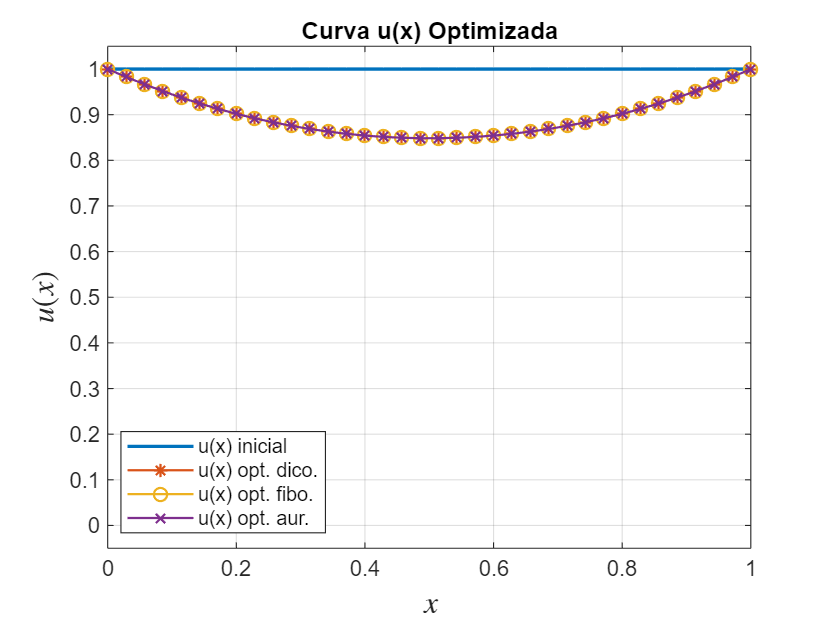

figure;
plot(x, u, 'LineWidth', 1.5); % u inicial
hold on;
plot(x, resultados(1).u_k, '-*', 'LineWidth', 1); % u optimizada
plot(x, resultados(2).u_k, '-o', 'LineWidth', 1); % u optimizada
plot(x, resultados(2).u_k, '-x', 'LineWidth', 1); % u optimizada
xlabel('$x$','Interpreter','latex','FontSize',14,'FontWeight','bold'); ylabel('$u(x)$','Interpreter','latex','FontSize',14,'FontWeight','bold');
ylim([-0.05, 1.05]);
title('Curva u(x) Optimizada');
legend(["u(x) inicial", "u(x) opt. dico.", "u(x) opt. fibo.", "u(x) opt. aur."], "Position", [0.1690 0.1861 0.2000, 0.0774])
grid on;

De nuevo comprobamos que en todos los casos la curva obtenida es la misma.

## Comparación con la solución exacta

Para el problema original, es conocido que la solución exacta es la curva catenaria, $u(x)=a\cosh{\Bigl(\frac{x-b}{a}\Bigr)}$. Las constantes se determinan imponiendo $u(0)=u(1)=1$. Resulta inmediato comprobar que $b=0.5$ por paridad del coseno hiperbólico. Para la constante $a$ se usa el método de Newton:

g = @(a)a*cosh(0.5/a)-1;
[a,~] = Newton(g,1e-10,0.7)

a = 0.8483

La solución exacta es, por lo tanto, $u(x)=0.84833\cosh{\Bigl(\frac{x-0.5}{0.84833}\Bigr)}$. Para comprobar si los resultados obtenidos anteriormente son correctos, a continuación se muestra su representación gráfica junto a la solución numérica obtenida empleando el método de búsqueda dicotómica. 

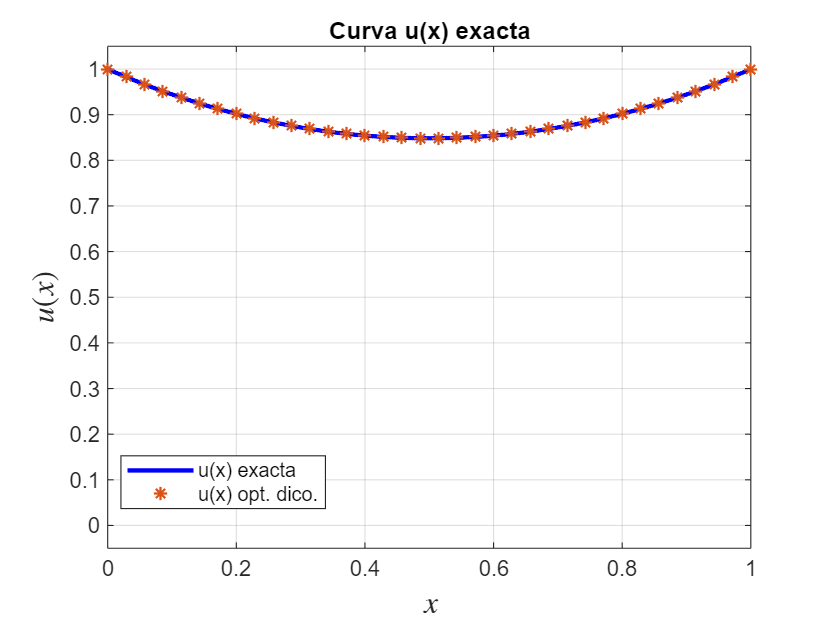

figure;
x_teo = linspace(0,1,1000);
y_teo = a*cosh((x_teo-0.5)/a);
plot(x_teo,y_teo,'b','LineWidth',2)
hold on;
plot(x, resultados(1).u_k, '*', 'LineWidth', 1); % u optimizada
xlabel('$x$','Interpreter','latex','FontSize',14,'FontWeight','bold'); ylabel('$u(x)$','Interpreter','latex','FontSize',14,'FontWeight','bold');
ylim([-0.05, 1.05]);
title('Curva u(x) exacta');
legend(["u(x) exacta", "u(x) opt. dico."], "Position", [0.1690 0.1861 0.2000, 0.0774])
grid on

Vemos como la solución numérica se aproxima perfectamente a la teórica.

A continuación se muestra una figura de la superficie de revolución resultante de girar la curva obtenida por las aproximaciones numéricas, o, lo que es lo mismo, la superficie que minimiza el área del problema original.

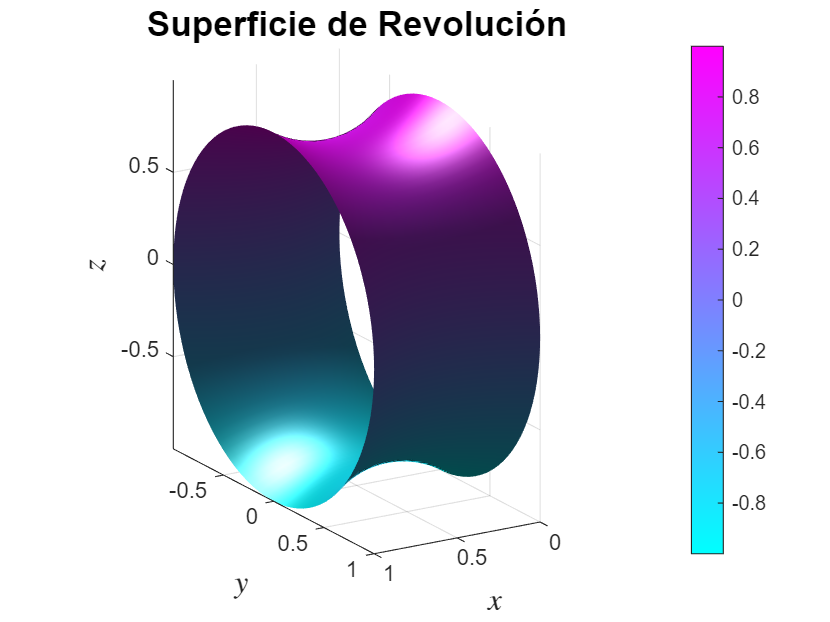

% Crear malla para la superficie de revolución (con el último resultado)
theta = linspace(0, 2*pi, 100); % Ángulo para el giro
[X, Theta] = meshgrid(x, theta); % Malla para x y theta
U = interp1(x, u_k, X(1, :)); % Valores de u(x) optimizados

% Coordenadas cartesianas para la superficie
Y = U .* cos(Theta); % Coordenada Y
Z = U .* sin(Theta); % Coordenada Z

% Graficar la superficie de revolución
figure;
surf(X, Y, Z, 'EdgeColor', 'none'); % Superficie suave
% Añadir detalles
shading interp; % Interpolación de colores para suavizar la superficie
colormap("cool"); 
colorbar; % Mostrar barra de colores
lighting phong; % Mejorar iluminación de la superficie
camlight right; % Añadir luz de cámara

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
zlabel('$z$', 'Interpreter', 'latex', 'FontSize', 14, 'FontWeight', 'bold');
title('Superficie de Revolución', 'FontSize', 16, 'FontWeight', 'bold');
axis equal; % Igualar las escalas de los ejes
grid on;

% Rotar la vista para apreciar mejor la figura
view([-211.16 18.39])

## Anexo: Funciones Necesarias

La siguiente función calcula el gradiente de un vector `u` en los puntos discretizados interiores:

function gk = calculo_gradiente(u, n)
    % gk: Vector con los gradientes calculados, donde gk(k) contiene el valor del gradiente para el índice k de u
    % u: Vector de valores u(x) en los puntos discretizados
    % n: Número de intervalos

    gk = zeros(size(u)); % Inicializar el gradiente

    % Para k = 1, ..., n-1 (índices interiores)
    for k = 2:n
        gk(k) = (1 / (2 * n)) * ( n^2 * (u(k) - u(k-1)) * (u(k-1) + u(k)) / sqrt(1 + n^2 * (u(k) - u(k-1))^2) + ...
            sqrt(1 + n^2 * (u(k) - u(k-1))^2) + ...
            sqrt(1 + n^2 * (u(k+1) - u(k))^2) - ...
            n^2 * (u(k+1) - u(k)) * (u(k) + u(k+1)) / sqrt(1 + n^2 * (u(k+1) - u(k))^2));
    end
    % Mantener gk(1) y gk(n+1) en cero (sin optimización), ya que u_0=1, u_n=1
    gk(1) = 0;
    gk(n+1) = 0;
end


La siguiente función calcula la función objetivo para calcular el área de la superficie de revolución:

function F = F(u, n)
    % F(u): Función objetivo para calcular el área de la superficie de revolución
    % u: Vector de valores u(x) en los puntos discretizados
    % n: Número de intervalos

    F = 0; % Inicializar el valor de F

    % Sumar cada término de la función objetivo
    for j = 1:n
        F = F + ((u(j) + u(j+1)) * sqrt(1 + n^2 * (u(j+1) - u(j))^2)) / (2 * n);
    end
end

 La siguiente función implementa el algoritmo de búsqueda dicotómica:

function [x_min, f_min, iter_bus] = busqueda_dicotomica(f, a, b, delta, it_max) % Método de búsqueda dicotómica
    eps = delta/10; % Distancia entre los puntos (epsilon < delta)
    iter_bus = 0; % Contador de iteraciones
    %Algoritmo
    while abs(b - a) > delta && iter_bus < it_max
        iter_bus = iter_bus + 1;
        % Calcular los dos puntos cercanos al punto medio
        x1 = (a + b) / 2 - eps / 2;
        x2 = (a + b) / 2 + eps / 2;
        % Evaluar la función en los puntos x1, x2 y actualizar intervalo
        if f(x1) < f(x2)
            b = x2;  % Reducir el límite superior
        else
            a = x1;  % Reducir el límite inferior
        end
    end
    % Resultado final
    x_min = (a + b) / 2;     
    f_min = f(x_min);
end

La siguiente función implementa el algoritmo de búsqueda de Fibonacci:

function [xa, fa, n_2] = fibo(f, intervalo, tol)
    % Está función aplica el método de la búesqueda de fibonacci a una función
    % para hayar un mínimo en un intervalo.
    % f: función unimodal en el intervalo, debe introducirse como función
    % anónima
    % intervalo: vector de dos componentes con los extremos del intervalo.
    % tol: tolerancia o error permitido, debe ser positivo
    %
    % Salidas: El método devuelve un vector [min, fval, iterados] 
    % min: punto donde se alncanza el minimo local de la función en el intervalo
    % fval: valor de la función en ese punto
    % iterados: número de iteraciones utilizadas para converger.
    % Calculamos los valores de la sucesión de Finonacci necesarios.
    fi = [1,1];
    b = intervalo(2);
    a = intervalo(1);
    w1 = b-a;
    n = 2;

    while w1 >= tol*fi(n)
        fi(n+1) = fi(n)+fi(n-1);
        n = n+1;
    end

    % Realizamos el primer paso a parte pues es el único con dos evaluaciones de f
    % y así después solo realizar una evaluación de f en cada paso.
    w1 = w1/fi(n)*fi(n-1);
    xa = b - w1;
    xb = a + w1;
    fa = f(xa);
    fb = f(xb);
    k = 2; % Número de pasos
    
    while and(k<= n-2, xa < xb) %La segunda condición es para evitar errores en caso de muchas iteraciones
        
        w1 = w1/fi(n-k+1)*fi(n-k);  
        
        if fa > fb % Actualizamos los valores según el valor de la función
            a = xa;
            xa = xb;
            fa = fb;
            xb = a + w1;
            fb = f(xb);
        else
            b = xb;
            xb = xa;
            fb = fa;
            xa = b-w1;
            fa = f(xa);
        end

        k = k+1;
    
    end

    n_2 = n-2;
end

La siguiente función implementa el método de búsqueda de la sección áurea:

function [opt,k,min] = SeccionAurea(f,delta,x1,x2)
    % Función que halla el mínimo de una función unimodal implementando
    % el método de la sección áurea. Los parámetros son la función objetivo
    % 'f' introducida como función anónima, la tolerancia 'delta' del método
    % y el intervalo [x1,x2] inicial. Se devuelve el valor del óptimo,
    % 'opt', de acuerdo con la tolerancia, el número de iteraciones 'k' y el 
    % mínimo valor de la función encontrado, 'min'.

    % Número áureo menos uno
    r = (sqrt(5)-1)/2;

    % Paso inicial del método
    a = x1;
    b = x2;
    y = a + (1-r)*(b-a);
    z = a + r*(b-a);
    k = 0;
    f1 = f(y);
    f2 = f(z);

    % Implementación del método (100 es el máximo número de iteraciones)
    while b-a > delta && k < 100

        if f1>=f2
            a = y;
            y = z;
            z = a + r*(b-a);
            f1 = f2;
            f2 = f(z);
        else
            b = z;
            z = y;
            y = a + (1-r)*(b-a);
            f2 = f1;
            f1 = f(y);
        end

        k = k + 1;

    end

    opt = (a+b)/2;
    min = f(opt);

end

La siguiente función implementa el método de Newton para hallar el cero simple de una función:

function [x,k]=Newton(f,delta,x0)
    % Función que implementa el método iterativo de Newton-Raphson para
    % calcular el cero simple de una función continuamente diferenciable en un
    % entorno de este. Toma por argumentos la función objetivo 'f' como función
    % anónima, la tolerancia 'delta' con la que se encuentra la solución y el punto
    % inicial 'x0' por el que se comienza a buscar. La función devuelve la
    % aproximación del valor donde ocurre el cero, 'x', y el número de
    % iteraciones empleadas 'k'.
    x = x0;
    k = 1;
    
    % Se crea una variable auxiliar simbólica, 'y', para calcular la derivada
    % de la función 'f'.
    syms y
    g(y) = f(y);
    dev_f = diff(g,y,1);
    
    % Proceso iterativo
    while abs(f(x)) > delta && k < 100
        x = x - f(x)/double(dev_f(x));
        k = k + 1;
    end

end